# Note Analysis of Biodata x Radar FMCW 60Ghz

clc
clear all
clc

## Biodata Processing

% biodata = ".dataset/Rifa_Rifa_2mindata_txt.mat";
biodata = ".dataset/Measurement_25042024_25042024-1_txt.mat";
load(biodata)

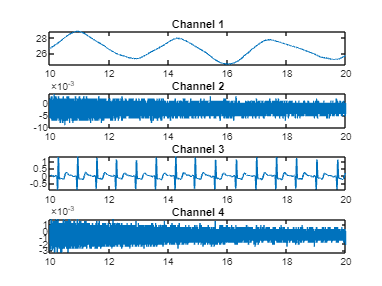

figure
% figure
subplot(4,1,1)
plot(bio_t,bio_ch1)
% xlim([10 20])
title('Channel 1');
subplot(4,1,2)
plot(bio_t,bio_ch2)
xlim([10 20])
title('Channel 2');
subplot(4,1,3)
plot(bio_t,bio_ch3)
% xlim([10 20])
title('Channel 3');
subplot(4,1,4)
plot(bio_t,bio_ch4)
xlim([10 20])
title('Channel 4');

breath = bio_ch1;
ecg = bio_ch3;


[breathpks,breathlocs] = findpeaks(breath,'MinPeakDistance',5000);
[ecgpks,ecglocs] = findpeaks(ecg,'MinPeakDistance',1000);

figure
subplot(2,1,1)
plot(bio_t,breath,"-",bio_t(breathlocs),breathpks,"*")
% xlim([10 20])
title('breath');
subplot(2,1,2)
plot(bio_t,ecg,"-",bio_t(ecglocs),ecgpks,"-*")
xlim([10 20])
title('ecg');

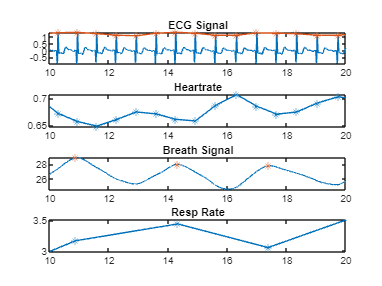

%% Ecg BPM Measure
peaks_len = size(ecglocs);
peaks_num= peaks_len(1);

dum_peak = zeros((peaks_num-1),1);
dum_peak_locs = zeros((peaks_num-1),1);

for(peak=2:peaks_num)
    dum_peak(peak-1) = 60/(bio_t(ecglocs(peak)) - bio_t(ecglocs(peak-1)));
    dum_peak_locs(peak-1) = bio_t(ecglocs(peak));
end

%% breath BPM Measure
breath_peaks_len = size(breathlocs);
breath_peaks_num= breath_peaks_len(1);

breath_dum_peak = zeros((breath_peaks_num-1),1);
breath_dum_peak_locs = zeros((breath_peaks_num-1),1);

for(breath_peak=2:breath_peaks_num)
    breath_dum_peak(breath_peak-1) = 60/(bio_t(breathlocs(breath_peak)) - bio_t(breathlocs(breath_peak-1)));
    breath_dum_peak_locs(breath_peak-1) = bio_t(breathlocs(breath_peak));
end

figure
% figure
subplot(4,1,1)
plot(bio_t,ecg,"-",bio_t(ecglocs),ecgpks,"-*")
xlim([10 20])
title('ECG Signal');
subplot(4,1,2)
plot(dum_peak_locs,dum_peak,"-*")
xlim([10 20])
title('Heartrate');
subplot(4,1,3)
plot(bio_t,breath,"-",bio_t(breathlocs),breathpks,"*")
xlim([10 20])
title('Breath Signal');
subplot(4,1,4)
plot(breath_dum_peak_locs,breath_dum_peak,"-*")
xlim([10 20])
title('Resp Rate');

## Radar Processing